Pendulum exercise

clear all
close all
clc

% Initialize simulation variables
Tsim = 10;
rel_tol= 1e-6;

% Initialize pendulum variables
M = 0.5;    % [kg] mass of the pendulum tip
l = 0.3;    % [m] length of the pendulum rod
c = 0.1;    % viscous friction coefficient
g = 9.81;    % [m/s^2] acceleration due to gravity

% Initial conditions
theta_init = pi/2; % initial angle [rad]
theta_dot_init = 0;   % initial angular velocity [rad/s]

Perform a simulation from initial conditions

simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;

Plot results

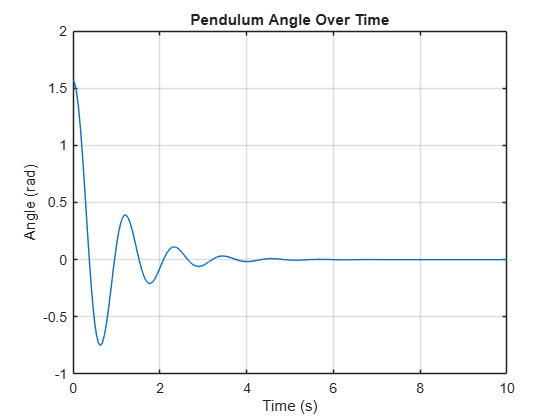

% Plot the results of the simulation
figure;
plot(t, theta);
xlabel('Time (s)');
ylabel('Angle (rad)');
title('Pendulum Angle Over Time');
grid on;